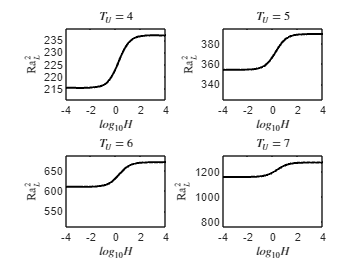

clear all
close all
clc
TUTU=[4 5 6 7];
risc=[1 2 6 20];
risc1=[0.5 3 10 40];

load dati.mat
xx = -4:0.1:4;

for i=1:length(TUTU)
    if TUTU(i)==4
        load Rc_logH_TU=4.mat
    end
    if TUTU(i)==5
        load Rc_logH_TU=5.mat
    end
    if TUTU(i)==6
        load Rc_logH_TU=6.mat
    end
    if TUTU(i)==7
        load Rc_logH_TU=7.mat
    end
    yy = spline(log10(HH),Rc,xx);
    subplot(2,2,i)
    plot(xx,yy,'k',LineWidth=1.5)
    tit=sprintf('$T_U=%d$',TUTU(i));
    title(tit,"Interpreter",'latex')
    xlabel('$log_{10} H$',Interpreter='latex')
ylabel('$\mathrm{Ra}_L^2$',Interpreter='latex')
    axis([-4 4 Rc(1)-10*risc1(i) Rc(end)+3*risc(i)])

    hold on
end